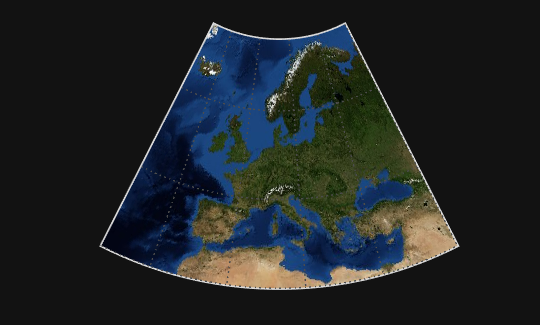

eox = wmsfind("eox");
eox_marble = refine(eox,"blue marble");
eox_marble_limits = refineLimits(eox_marble,Latlim=[-90 90]);
eox_update = wmsupdate(eox_marble_limits);
europe = geocode("Europe");
[latlim,lonlim] = bounds(europe.Shape);
[A,R] = wmsread(eox_update,Latlim=latlim,Lonlim=lonlim);
figure
worldmap(latlim,lonlim)
geoshow(A,R)
plabel off
mlabel off